%{
ES115 Engineering Computer Applications
Module 5 Project: Two-Sensor Calibration and Agreement Check

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project calibrates and compares two different sensors using linear
models. Each sensor is defined using two calibration points, and linear
equations are created from those points. The goal is to evaluate both
sensor outputs over a range of inputs, compare their readings, and
determine where they agree the most by analyzing the error between them.

Inputs (Knowns):
- Calibration points for Sensor 1: (0, 5) and (10, 25)
- Calibration points for Sensor 2: (0, 3) and (10, 27)
- Input values (x) from 0 to 30
- Linear model form: y = mx + b

Outputs (Unknowns):
- Linear equations for both sensors
- Sensor output values over the input range
- Graph comparing both sensor outputs
- Error between the two sensors
- Graph of error vs input
- Input value where the sensors agree the most (minimum error)

Engineering Workflow and Algorithms:
- Define calibration points for both sensors
- Calculate slope (m) and intercept (b) for each sensor
- Create linear equations using computed values
- Evaluate both models over a range of inputs
- Plot both sensor outputs for comparison
- Compute error between the two sensors
- Plot error vs input
- Find the input where absolute error is minimized

MATLAB Tools / Functions Used:
- plot() for graphing
- basic arithmetic for slope and intercept calculations
- min() to find smallest error value
- abs() for absolute error comparison
- indexing to locate corresponding input values
- fprintf() for displaying results

Reflection After Completing the Project:
- I learned how to create linear calibration models from data points and
  compare multiple sensors using error analysis.
- I also understood how differences in slope and intercept affect sensor
  readings and how to find where two models agree the most.
- If I were to improve this, I would test more calibration points or use
  real data to make the comparison more accurate.
- Difficulty Rating: 5/10 — the calculations were simple, but analyzing
  the agreement between sensors required more attention.
%}



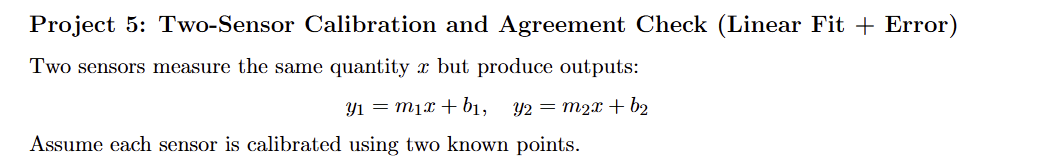

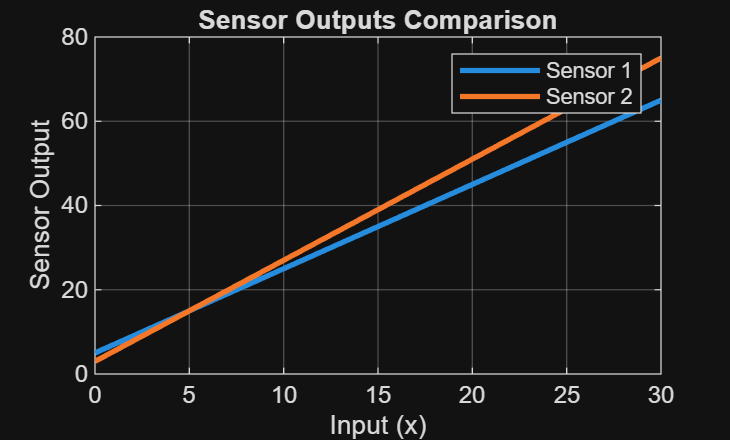


clear; clc; close all; 
 
% ---------------------------- 
% Calibration points (chosen) 
 
% Sensor 1 points 
x1_pts = [0 10]; 
y1_pts = [5 25]; 
 
% Sensor 2 points 
x2_pts = [0 10]; 
y2_pts = [3 27]; 
 
% ---------------------------- 
% Compute slopes and intercepts 
 
% Sensor 1 
m1 = (y1_pts(2) - y1_pts(1)) / (x1_pts(2) - x1_pts(1)); 
b1 = y1_pts(1) - m1*x1_pts(1); 
 
% Sensor 2 
m2 = (y2_pts(2) - y2_pts(1)) / (x2_pts(2) - x2_pts(1)); 
b2 = y2_pts(1) - m2*x2_pts(1); 
 
% ---------------------------- 
% Evaluate models 
x = 0:1:30; 
 
y1 = m1*x + b1; 
y2 = m2*x + b2; 
 
% ---------------------------- 
% Plot both sensors 
figure; 
plot(x, y1, 'LineWidth', 2); hold on; 
plot(x, y2, 'LineWidth', 2); 
 
title('Sensor Outputs Comparison'); 
xlabel('Input (x)'); 
ylabel('Sensor Output'); 
legend('Sensor 1', 'Sensor 2'); 
grid on; 

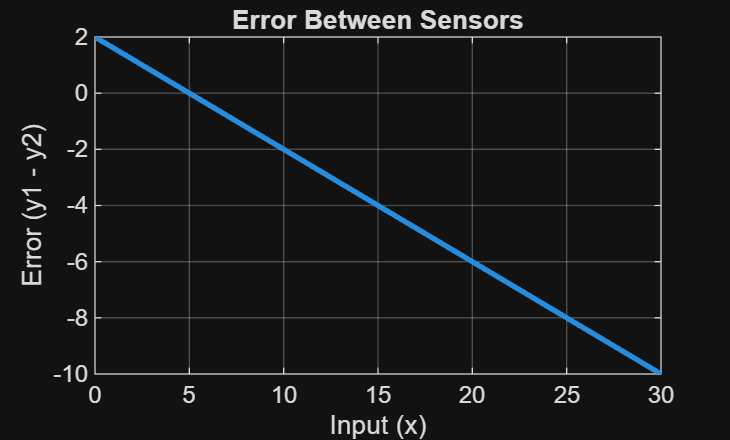

 
% ---------------------------- 
% Compute error 
e = y1 - y2; 
 
% Plot error 
figure; 
plot(x, e, 'LineWidth', 2); 
 
title('Error Between Sensors'); 
xlabel('Input (x)'); 
ylabel('Error (y1 - y2)'); 
grid on; 

 
% ---------------------------- 
% Find best agreement (minimum absolute error) 
[~, idx] = min(abs(e)); 
x_best = x(idx); 
e_best = e(idx); 
 
fprintf('Best agreement at x = %.2f with error = %.2f\n', x_best, e_best); 

Best agreement at x = 5.00 with error = 0.00
